# Seperating Moon in the image

img = imread('moon.tif');
threshold = graythresh(img);

[r,c] = size(img);
mask = imbinarize(img,threshold);
% Changing the threshold will change the black and white areas in the image

% we cannot use im2double to convert mask image into double image
mask_double = zeros(r,c);

for i=1:r
    for j=1:c
        if mask(i,j) == 1
            mask_double(i,j) = 1;
        end
    end
end

final_img = im2double(img) .* mask_double;
%imshowpair(img, mask,'montage')
subplot(1,3,1), imshow(img);
subplot(1,3,2), imshow(mask);
subplot(1,3,3), imshow(final_img);

# Finding image boundary

clc;
clear all;
link_img = imread('linkoln.jpg');
structuring_ele = strel('square', 3);
dilated_img = imdilate(link_img, structuring_ele);

boundary = dilated_img - link_img;

imshowpair(link_img, boundary, 'montage');

# Finding no of coins

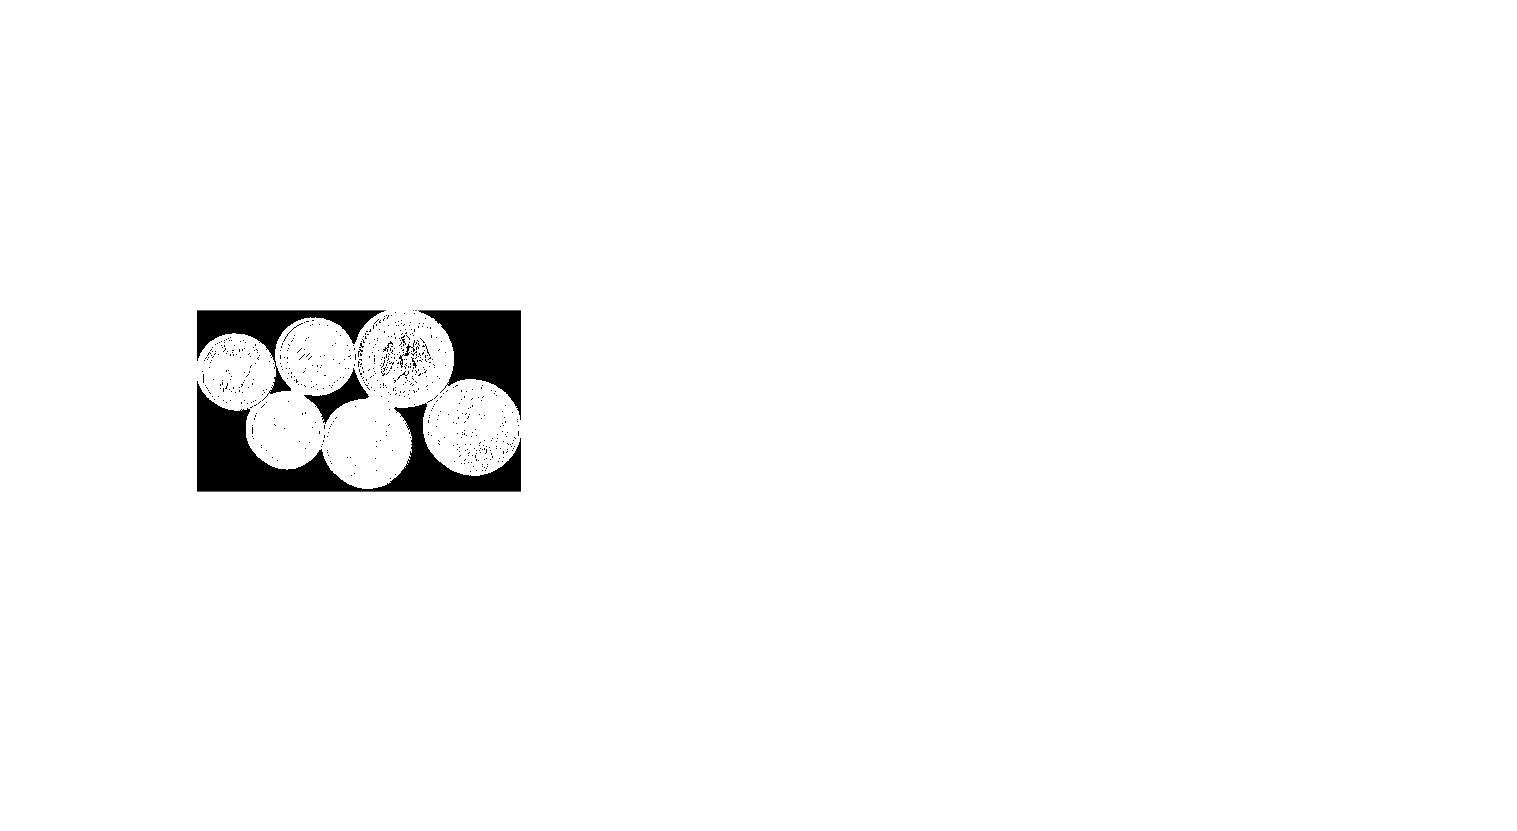

clc;
clear all;

coins = imread('Coins.jpg');
gray = rgb2gray(coins);
threshold = graythresh(gray);

bw = imbinarize(gray, threshold);
[r, c] = size(bw);
bw = imfill(bw, 'holes');
matone = ones(r,c);
se = strel('disk', 50);
bw = matone-bw;
% bw = imopen(bw,se);
% bw = imfill(matone-bw);
imshow(bw);


% eroded_img = imerode(matone-bw, se);
% eroded_img = imfill(eroded_img);
% se = strel('disk', 20);
% eroded_img = imerode(eroded_img, se);
% imshow(eroded_img)

stat = regionprops(bw, 'Centroid', 'MajoraxisLength', 'MinoraxisLength');
centers = stat.Centroid;
diameters = mean([stat.MajorAxisLength stat.MinorAxisLength],2);
radiuses = diameters / 2

radiuses = 503.3436